# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 4.2: ejercicio 04  - Texturas

El objetivo de este ejercicio la caracterización de texturas. Para ello, sobre imágenes con texturas diferentes, se obtendrán y compararán los valores de entropía, las matrices de coocurrencia en niveles de gris (GLCM) y estadísticas de las GLCM para diversos valores del vector de *offset*.

Paso 1) Lectura de las imágenes.

% === TEMA 4.2: EJERCICIO 04 - TEXTURAS ===
clear all
close all

% --- FUNCIÓN AUXILIAR PARA GARANTIZAR ESCALA DE GRISES (2-D) ---
function I_gray = ensureGrayscale(I)
    % Convierte la imagen I a escala de grises (2D) de forma robusta.
    if isempty(I)
        I_gray = [];
        return;
    end
    
    if size(I, 3) == 3
        % Es RGB, convertir a escala de grises
        I_gray = rgb2gray(I);
    elseif islogical(I) || isnumeric(I)
        % Ya es una imagen de intensidad (o binaria)
        I_gray = I;
    else
        % Caso de imagen indexada o formato inusual, intentar usar im2gray
        try
            I_gray = im2gray(I);
        catch
            warning('Tipo de imagen no compatible para la conversión a escala de grises.');
            I_gray = I; % Devolver original si falla la conversión
        end
    end
end
% ------------------------------------------------------------------


% Paso 1) Lectura de las imágenes. (CÓDIGO DE LA PROFESORA)
clear all
close all
% textures from http://www.cb.uu.se/~gustaf/texture/
imagenames = {'texture-stone.png','texture-sand.png','texture-linseeds.png', ...
              'texture-canvas.png','texture-pattern1.png','texture-pattern2.png'};


textureImg=[];
for n=1:length(imagenames)
    textureImg{n} = imread(imagenames{n});
end

% AÑADIDO: Conversión a escala de grises para el análisis (requerido por entropy, GLCM)
textureImg_gray = {};
for n=1:length(textureImg)
    textureImg_gray{n} = ensureGrayscale(textureImg{n}); 
end


% Paso 2) Entropía: Calcule la entropía de las imágenes de patrones, ordénelas y muéstrelas.
fprintf('--- Paso 2: Entropía ---\n');

--- Paso 2: Entropía ---


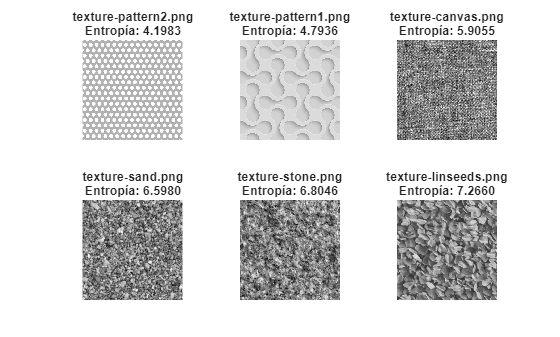


entropia_vals = zeros(1, length(textureImg_gray));
for n = 1:length(textureImg_gray)
    entropia_vals(n) = entropy(textureImg_gray{n});
end

% Ordenar la entropía y obtener los índices de ordenación
[sorted_entropia, I] = sort(entropia_vals);

% Mostrar las imágenes y su entropía en orden creciente
figure('Name', 'Imágenes Ordenadas por Entropía Creciente (Baja a Alta)');
for n = 1:length(I)
    idx = I(n);
    subplot(2, 3, n);
    imshow(textureImg{idx});
    title(sprintf('%s\nEntropía: %.4f', imagenames{idx}, sorted_entropia(n)), 'Interpreter', 'none');
end


fprintf('Imágenes ordenadas por Entropía (menor a mayor):\n');

Imágenes ordenadas por Entropía (menor a mayor):


for n = 1:length(I)
    fprintf('  %d. %s (%.4f)\n', n, imagenames{I(n)}, sorted_entropia(n));
end

  1. texture-pattern2.png (4.1983)
  2. texture-pattern1.png (4.7936)
  3. texture-canvas.png (5.9055)
  4. texture-sand.png (6.5980)
  5. texture-stone.png (6.8046)
  6. texture-linseeds.png (7.2660)



% Justificación de la menor entropía:
fprintf('\n¿Qué imagen tiene la menor entropía y por qué?\n');


¿Qué imagen tiene la menor entropía y por qué?


fprintf('La imagen con menor entropía será probablemente una de patrón (pattern1/pattern2).\n');

La imagen con menor entropía será probablemente una de patrón (pattern1/pattern2).


fprintf('Justificación: La entropía es una medida de la aleatoriedad. Una imagen con un patrón\n');

Justificación: La entropía es una medida de la aleatoriedad. Una imagen con un patrón


fprintf('simple y repetitivo (patrones artificiales) tiene una distribución de intensidad muy\n');

simple y repetitivo (patrones artificiales) tiene una distribución de intensidad muy


fprintf('predecible y baja complejidad, resultando en un valor de entropía bajo.\n');

predecible y baja complejidad, resultando en un valor de entropía bajo.




% Paso 3) GLCM (Matriz de coocurrencia de niveles de gris).
fprintf('\n--- Paso 3: Cálculo de GLCMs ---\n');


--- Paso 3: Cálculo de GLCMs ---



len = 5;
% [row_offset, col_offset]
% Direcciones: 0º([0, len]), 45º([-len, len]), 90º([-len, 0]), 135º([-len, -len])
offsets = [0 len; -len len; -len 0; -len -len]; 

%co-ocurrence matrix
% Calculamos las GLCMs para la primera imagen (texture-stone.png, índice 1)
img_index = 1; 
I_demo = textureImg_gray{img_index};

% Usamos 8 niveles de gris para obtener una GLCM 8x8, más fácil de interpretar.
glcms = graycomatrix(I_demo, 'Offset', offsets, 'Symmetric', true, 'NumLevels', 8);

fprintf('GLCMs calculadas para %s con offsets:\n', imagenames{img_index});

GLCMs calculadas para texture-stone.png con offsets:


disp(offsets);

     0     5
    -5     5
    -5     0
    -5    -5





% Paso 4) Muestra la imagen de la primera GLCM con colores escalados.
fprintf('\n--- Paso 4: Visualización de la Primera GLCM (0º) ---\n');


--- Paso 4: Visualización de la Primera GLCM (0º) ---


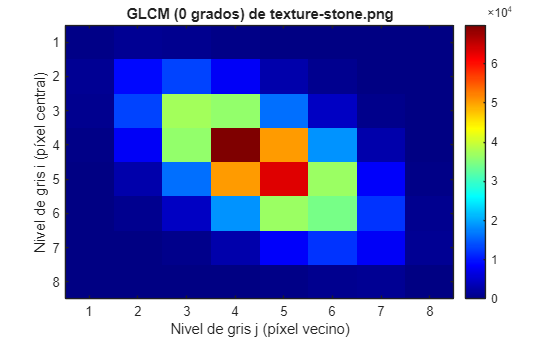


glcm1 = glcms(:,:,1); % Primera matriz (corresponde a 0 grados, distancia 5)

figure('Name', 'Visualización de la Primera GLCM (0 grados, Distancia 5)');
imagesc(glcm1);
colormap jet;
colorbar;
title(sprintf('GLCM (0 grados) de %s', imagenames{img_index}), 'Interpreter', 'none');
xlabel('Nivel de gris j (píxel vecino)');
ylabel('Nivel de gris i (píxel central)');



% Paso 5) Obtenga y visualice los estadísticos Contrast, Correlation, Energy y Homogeneity
fprintf('\n--- Paso 5: Estadísticos de GLCM ---\n');


--- Paso 5: Estadísticos de GLCM ---



% Definir varios vectores de offset diferentes
test_offsets = [1 0; 1 1; 0 5; 5 0]; % 90 deg (len=1), 45 deg (len=1), 0 deg (len=5), 90 deg (len=5)
offsets_names = {'90 deg, dist 1', '45 deg, dist 1', '0 deg, dist 5', '90 deg, dist 5'};

% Índices de las imágenes a analizar
idx_linseeds = 3; % 'texture-linseeds.png'
idx_pattern2 = 6; % 'texture-pattern2.png'

img_linseeds = textureImg_gray{idx_linseeds};
img_pattern2 = textureImg_gray{idx_pattern2};


% Función auxiliar para calcular y mostrar estadísticos (incluida en el script principal)
function calculateAndDisplayProps(img, img_name, offsets, names)
    fprintf('\nEstadísticos para: %s\n', img_name);
    
    % Calcular GLCMs (Usando 8 niveles para uniformidad en el cálculo)
    glcms_local = graycomatrix(img, 'Offset', offsets, 'NumLevels', 8, 'Symmetric', true);
    
    % Obtener y mostrar las propiedades GLCM
    props = graycoprops(glcms_local, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});
    
    T = table(names', props.Contrast', props.Correlation', props.Energy', props.Homogeneity', ...
                        'VariableNames', {'Offset', 'Contrast', 'Correlation', 'Energy', 'Homogeneity'});
    disp(T);
end

calculateAndDisplayProps(img_linseeds, imagenames{idx_linseeds}, test_offsets, offsets_names);


Estadísticos para: texture-linseeds.png
          Offset          Contrast    Correlation     Energy     Homogeneity
    __________________    ________    ___________    ________    ___________

    {'90 deg, dist 1'}    0.18532       0.94396       0.14636      0.91078  
    {'45 deg, dist 1'}    0.20176       0.93899       0.14111      0.90263  
    {'0 deg, dist 5' }     1.1175       0.66202      0.070342       0.7177  
    {'90 deg, dist 5'}     1.1435       0.65433      0.069294      0.71255  



calculateAndDisplayProps(img_pattern2, imagenames{idx_pattern2}, test_offsets, offsets_names);


Estadísticos para: texture-pattern2.png
          Offset          Contrast    Correlation    Energy     Homogeneity
    __________________    ________    ___________    _______    ___________

    {'90 deg, dist 1'}    0.11205       0.93826      0.45101      0.96031  
    {'45 deg, dist 1'}    0.18173       0.89986      0.43503      0.94824  
    {'0 deg, dist 5' }    0.78539        0.5673      0.32328      0.84462  
    {'90 deg, dist 5'}     0.7914       0.56412      0.32299      0.84405  

